# Tutorial for DHB representation

Andy Park, Nov 2023.

The goal of this tutorial is as follows:

Given a few data from demonstrations, I should demonstrate using the shape descriptor to generalize a demonstration data for affine transform capabilities: 

- Various initial and target locations — position / orientations

- Varying the scale → reproducing it in different magnitude

- Change of viewpoint / rotational transform of the entire trajectory

Time scaling 

- Given the invariant descriptor, demonstrate the generalization in different speeds. Varying constant speed and varying speed in mid-motion.

- If we can show that we could use this for SNS based

Representation Singularity-handling 

- In each of the singular / ambiguous state of the representation, show how it can be handled smoothly based on the concept presented in the paper.

Additional constraints handling 

- Generate a novel trajectory that can meet new constraints while keeping the similarity in the shape based on the descriptor.

## Input Preparation

#### Load measurements and convert to pose data

% loading pose data, format: rows=samples, columns=x|y|z|qx|qy|qz|qw
% note: you can also use marker data together with the function markers2pose.m

clc; clear all; close all;

load data/vive_data.mat
N = length(measured_pose_coordinates);
dt = 1/60; % timestep

% Convert quaternion to rotation matrix
pos_data = measured_pose_coordinates(:,2:4); % position
rotm_data = zeros(3,3,N);
T_data = zeros(4,4,N);
rvec_data = zeros(N, 3);
for i=1:N    
    % [qw, qx, qy, qz]
    pos = pos_data(i,:)';
    qt = [measured_pose_coordinates(i,8), measured_pose_coordinates(i,5:7)];
    rotm = quat2rotm(qt); % rotation matrix
    angvec = rotm2axang(rotm); % angle and axis
    rvec = angvec(4) * angvec(1:3); % rotation vector
    T = [rotm, pos; 0 0 0 1];

    % store the data
    rotm_data(:,:,i) = rotm;
    rvec_data(i, :) = rvec;
    T_data(:,:,i) = T;
end

% Get the initial transform
T0 = [rotm_data(:,:,1) pos_data(1,:)'; 0 0 0 1];

% get the pos diff data
pos_diff_data = diff(pos_data);

#### Compute DHB invariants

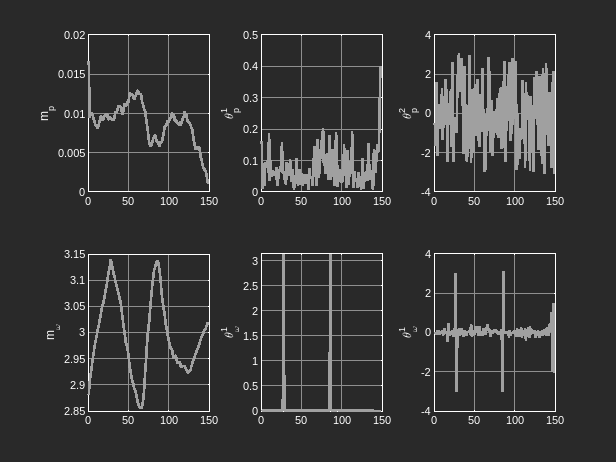

% Compute position based DHB invariants
[linear_motion_invariant, angular_motion_invariant, linear_frame_initial, angular_frame_initial] = computeDHB2(pos_diff_data, rvec_data(1:end-1,:), 'pos', T0);
invariants_pos = [linear_motion_invariant, angular_motion_invariant];

% Plot the invariants
figure('NumberTitle', 'off', 'Name', 'Cartesian pose to DHB');

dhbInvNames = {'m_p' '\theta_p^1' '\theta_p^2' 'm_{\omega}' '\theta_{\omega}^1' '\theta_{\omega}^1'};
for i=1:6
    subplot(2,3,i)
    plot(invariants_pos(:,i),'k','LineWidth',2)
    ylabel(dhbInvNames{i});
    grid on
end
plot_darkmode

#### Reconstruct the original trajectory

% position
[pos_r_data, rvec_r_data] = reconstructTrajectory2(invariants_pos, linear_frame_initial, angular_frame_initial, 'pos');

% compute reconstruction errors
errSP_pos = [(pos_r_data - pos_data(1:end-3,:)).^2 (rvec_r_data - rvec_data(1:end-3,:)).^2];

% Compute rmse error
err_pos = zeros(1,6);
for i=1:6
    err_pos(i) = sum(errSP_pos(:,i));
end

RMSE_pos = sqrt([sum(err_pos(1:3)) sum(err_pos(4:6))]./(N-2));
disp(['Reconstruction errors in pose (RMSE): ' num2str(RMSE_pos)])

Reconstruction errors in pose (RMSE): 2.3801e-16  2.3838e-15


#### Plot the original and reconstructed paths

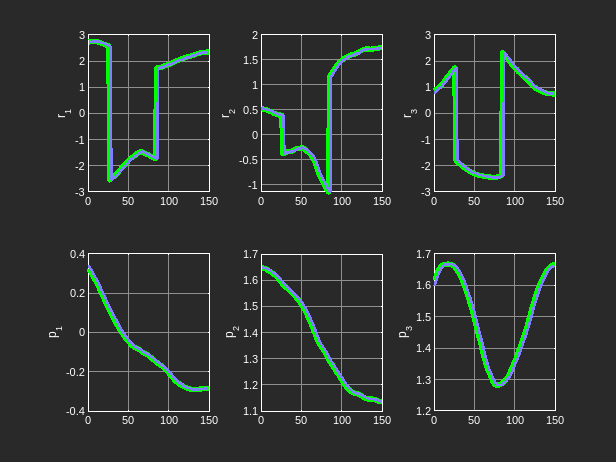

% Plot original and reconstructed paths -- position
pose_data = [rvec_data, pos_data]; % original
pose_r_data = [rvec_r_data, pos_r_data]; % reconstructed

figure('NumberTitle', 'off', 'Name', 'DHB to Cartesian pose');
for i=1:6
    subplot(2,3,i)
    plot(pose_data(3:end,i),'g','LineWidth',4)
    hold on;
    plot(pose_r_data(:,i),'b','LineWidth',2)        
    if(i<4)
        ylabel(['r_' num2str(i)])
    else
        ylabel(['p_' num2str(i-3)])
    end
    grid on
end
plot_darkmode

#### Plot the original and reconstructed paths in 3D

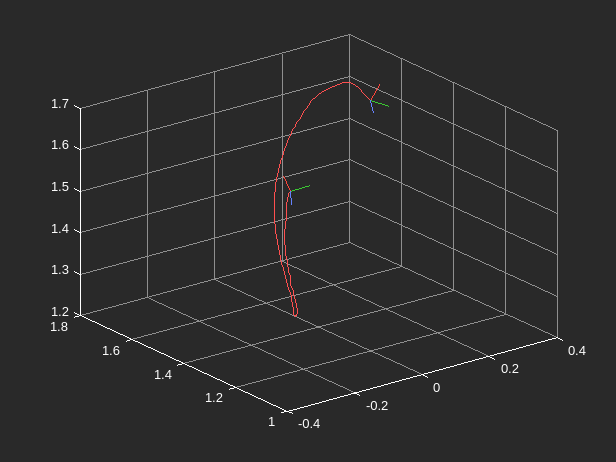

% Convert the rotation vector data into rotation matrix and
% reconstruct the transform data.
rotm_r_data = zeros(3, 3, N-3);
T_r_data = zeros(4, 4, N-3);
qt_r_data = zeros(N-3, 4);
for i=1:size(rvec_r_data,1)
    p_r = pos_r_data(i,:);
    rvec_r = rvec_r_data(i,:);
    rotm_r = rotationVectorToMatrix(rvec_r);
    qt_r = rotm2quat(rotm_r);
    T_r = [rotm_r, p_r'; 0 0 0 1];

    rotm_r_data(:,:,i) = rotm_r;
    T_r_data(:,:,i) = T_r;
    qt_r_data(i, :) = qt_r;
end

% plot 3D trajectory
figure;
plot3(pos_data(1:N-3,1), pos_data(1:N-3,2), pos_data(1:N-3,3), 'b');
hold on;
plot3(pos_r_data(:,1), pos_r_data(:,2), pos_r_data(:,3), 'r');
plotTransforms(pos_r_data(1,:), qt_r_data(1,:), 'FrameSize', 0.05);
plotTransforms(pos_r_data(end,:), qt_r_data(end,:), 'FrameSize', 0.05);
grid on;
plot_darkmode;

### Validate the invariance with affine transforms

Here, we show that with the changes made to input motions', the shape descriptors remain unchanged.

% Apply affine transform to the pos data
% pos_offset = [1 3 4];
pos_offset = [0 0 0];
% eul = [pi/5 pi/3 pi/6];
eul = [0 0 0];
rotmZYX_offset = eul2rotm(eul);

pos_tr_data = rotmZYX_offset * pos_data';
pos_tr_data = pos_tr_data' + pos_offset;

% get rotation matrix data
rotm_tr_data = zeros(size(rotm_data));
rvec_tr_data = zeros(size(rotm_data,1),3);
for i=1:N
    rotm_tr = rotmZYX_offset * rotm_data(:,:,i);    
    angvec_tr = rotm2axang(rotm_tr); % angle and axis
    rvec_tr = angvec_tr(4) * angvec_tr(1:3);
    rvec_tr_data(i,:) = rvec_tr;
    rotm_tr_data(:,:,i) = rotm_tr;
end

% get position and rotation diff data
pos_tr_diff_data = diff(pos_tr_data);

% get the initial pose with transform
T0_tr = T0;
T0_tr(1:3,3) = pos_tr_data(1,:)';
T0_tr(1:3,1:3) = rotm_tr_data(1:3,1:3,1);

% Compute position based DHB invariants
[linear_motion_invariant_tr, angular_motion_invariant_tr, linear_frame_initial_tr, angular_frame_initial_tr] = computeDHB2(pos_tr_diff_data, rvec_tr_data(1:end-1,:), 'pos', T0_tr);
invariants_pos_tr = [linear_motion_invariant_tr, angular_motion_invariant_tr];

% compute reconstruction errors
err_invariant = [(linear_motion_invariant_tr - linear_motion_invariant).^2 (angular_motion_invariant_tr - angular_motion_invariant).^2];

% Compute rmse error
err_invariant_sum = zeros(1,6);
for i=1:6
    err_invariant_sum(i) = sum(err_invariant(:,i));
end

RMSE_invariant = sqrt([sum(err_invariant_sum(1:3)) sum(err_invariant_sum(4:6))]./(N-3));
disp(['Errors (RMSE) between invariants with affine transforms: ' num2str(RMSE_invariant)])

Errors (RMSE) between invariants with affine transforms: 0  0


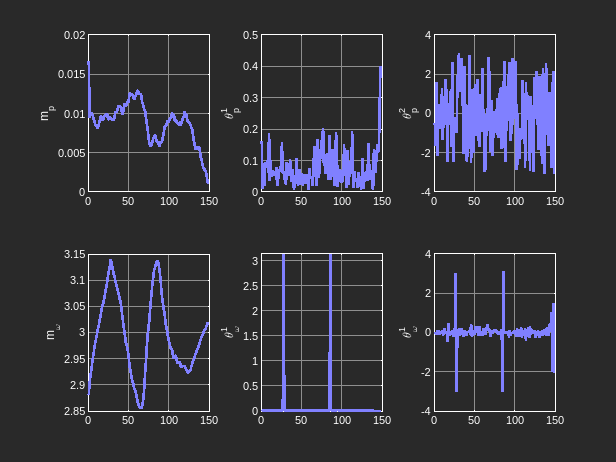

% Plot the invariants
figure('NumberTitle', 'off', 'Name', 'Cartesian pose to DHB (w/ transform)');

dhbInvNames = {'m_p' '\theta_p^1' '\theta_p^2' 'm_{\omega}' '\theta_{\omega}^1' '\theta_{\omega}^1'};
for i=1:6
    subplot(2,3,i)
    plot(invariants_pos(:,i),'r','LineWidth',2)
    hold on;
    plot(invariants_pos_tr(:,i),'b','LineWidth',2)
    ylabel(dhbInvNames{i});
    grid on
end
plot_darkmode